# PRÁCTICA 9: SOLUCIONES BASADAS EN *STATISTICAL LEARNING* Y EMPAREJAMIENTO

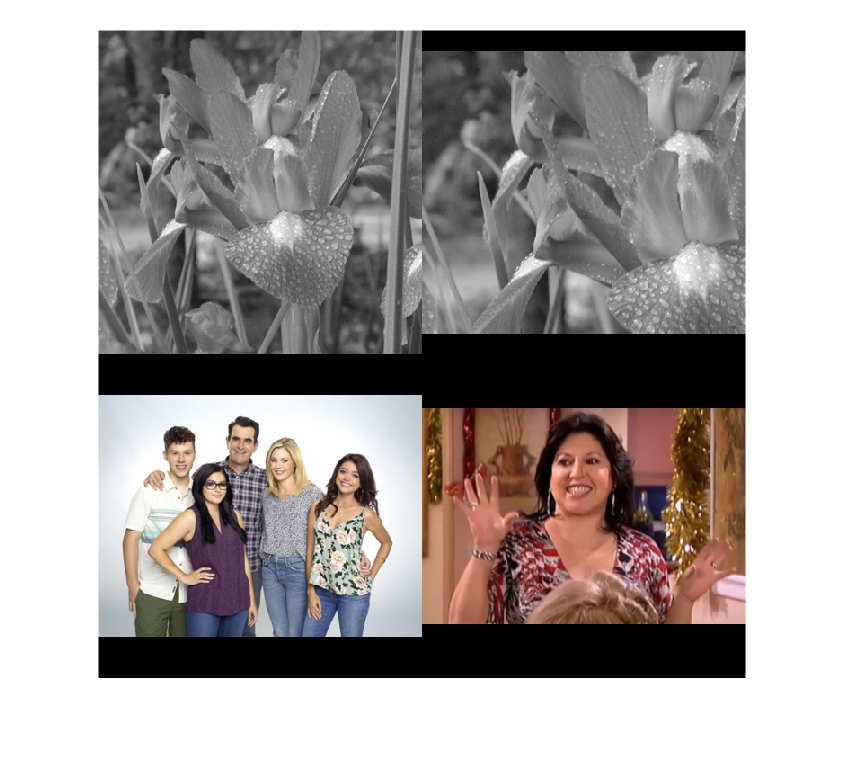

% Cargamos las imagenes que se usaran en la sesión práctica

flores1 = imread("flores_1.tif");
flores2 = imread("flores_2.tif");
flores2 = flores2(:,:,1:3);
familia = imread('familia.jpeg');
paloma = imread('las_caras_juan.jpg');

% Para el emparejamiento de plantillas, hemos de trabajar con 
% imagenes en escala de grises.

flores1 = rgb2gray(flores1);
flores2 = rgb2gray(flores2);

montage({flores1,flores2,familia,paloma})

## Emparejamiento de plantillas

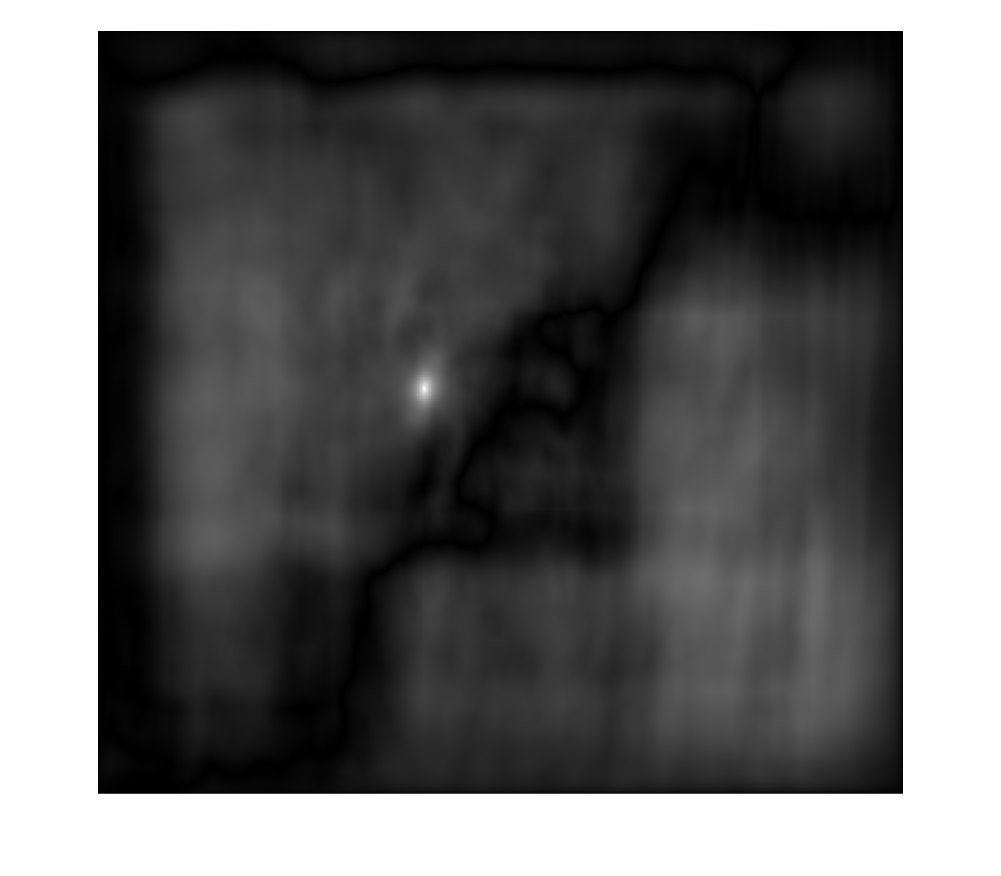

% Calcular el mapa definido por el coeficiente de correlación de la 
% plantilla sobre la imagen original. Los puntos blancos indican una
% correlación positiva, mientras que los puntos negros indican una
% correlación negativa.

mapa_corr = abs(normxcorr2(flores2,flores1));

imshow(mapa_corr,[]);


% Encontrar el valor máximo en el mapa de correlación, para saber que pixel
% en la imagen original se corresponde exactamente al punto de emparejamiento
% entre dicha imagen y la plantilla

idx = find(mapa_corr > 0.99);

% Numero de elementos emparejados (solo debería de haber uno)

numel(idx)

ans = 1

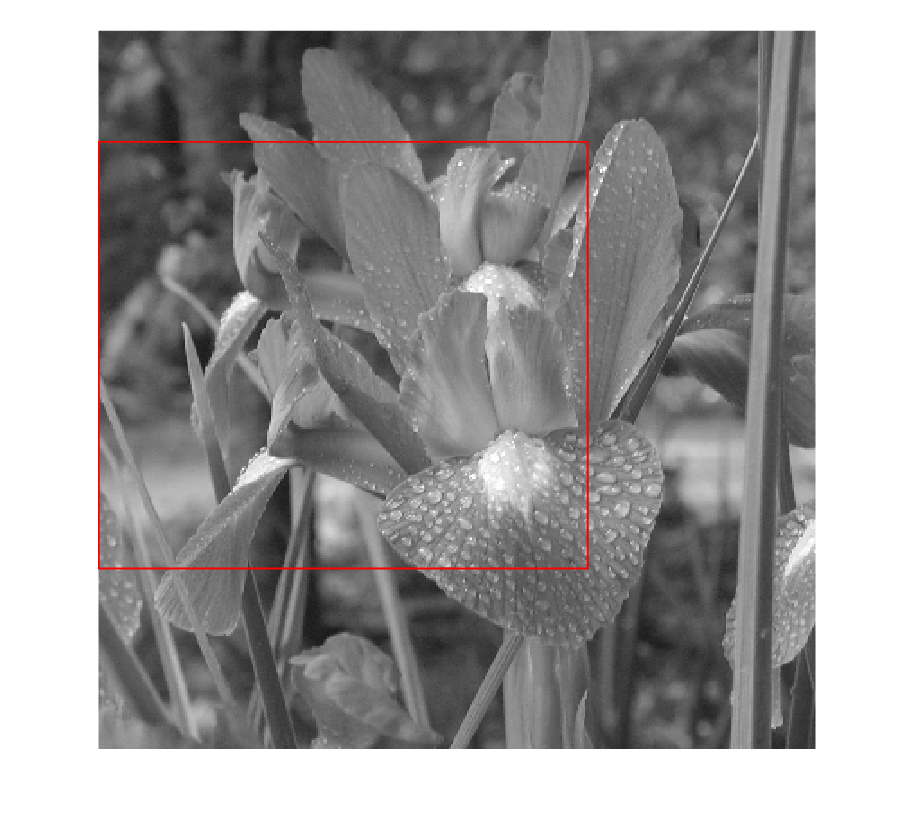


% En el mapa de correlación, 'idx' indica las posiciones donde la
% correlación entre la plantilla y la imagen es muy alta ( > 0.99 ).
% A partir de ese índice lineal recuperamos las coordenadas (fila, columna)
% dentro del propio mapa de correlación.

[fila, columna] = ind2sub(size(mapa_corr), idx);

% Obtenemos el tamaño de la plantilla y calculamos aproximadamente
% "medio tamaño" en vertical y en horizontal. Estos valores se usarán
% para desplazar la posición del máximo y construir la ventana.

[filas_flores2, columnas_flores2] = size(flores2);
flores2_pixel_central_x = floor(filas_flores2/2);
flores2_pixel_central_y = floor(columnas_flores2/2);

% PRIMER AJUSTE:
% Desplazamos la posición del máximo de correlación restando medio tamaño
% de la plantilla. Este desplazamiento compensa cómo se ha generado
% el mapa de correlación y aproxima esta posición a la zona donde
% debería estar el centro de la plantilla en la imagen.

fila    = fila    - flores2_pixel_central_x;
columna = columna - flores2_pixel_central_y;

% Hacemos una copia de la imagen de referencia sobre la que
% vamos a superponer la plantilla.

imagen_unida = flores1;

% SEGUNDO AJUSTE:
% A partir de esa posición ya "corregida", calculamos ahora la esquina
% superior izquierda de la ventana donde irá la plantilla. De nuevo
% restamos medio tamaño de la plantilla, de forma que la ventana
% cubra justo el área que ocupará la plantilla al superponerse.

fila_inicial    = fila    - flores2_pixel_central_x;
columna_inicial = columna - flores2_pixel_central_y;

% Con la esquina superior izquierda y el tamaño de la plantilla,
% obtenemos la esquina inferior derecha de la ventana (en índices
% de la matriz imagen_unida).

fila_final    = fila_inicial    + filas_flores2;
columna_final = columna_inicial + columnas_flores2;

% Copiamos la plantilla dentro de esa ventana de la imagen grande.
% El +1 aparece porque los índices de inicio se han definido como
% “antes” de la zona en la que realmente queremos escribir.

imagen_unida(fila_inicial+1:fila_final,columna_inicial+1:columna_final) = flores2;

imshow(imagen_unida)
hold on

% Dibujamos el rectángulo que delimita exactamente la ventana donde
% se ha insertado la plantilla: origen en la esquina superior izquierda
% (columna_inicial+1, fila_inicial+1) y tamaño igual al de la plantilla.

rectangulo = rectangle('Position',[columna_inicial+1, fila_inicial+1, columnas_flores2, filas_flores2],'EdgeColor', 'r', 'LineWidth', 1);
hold off

## Clasificador de la minima distancia

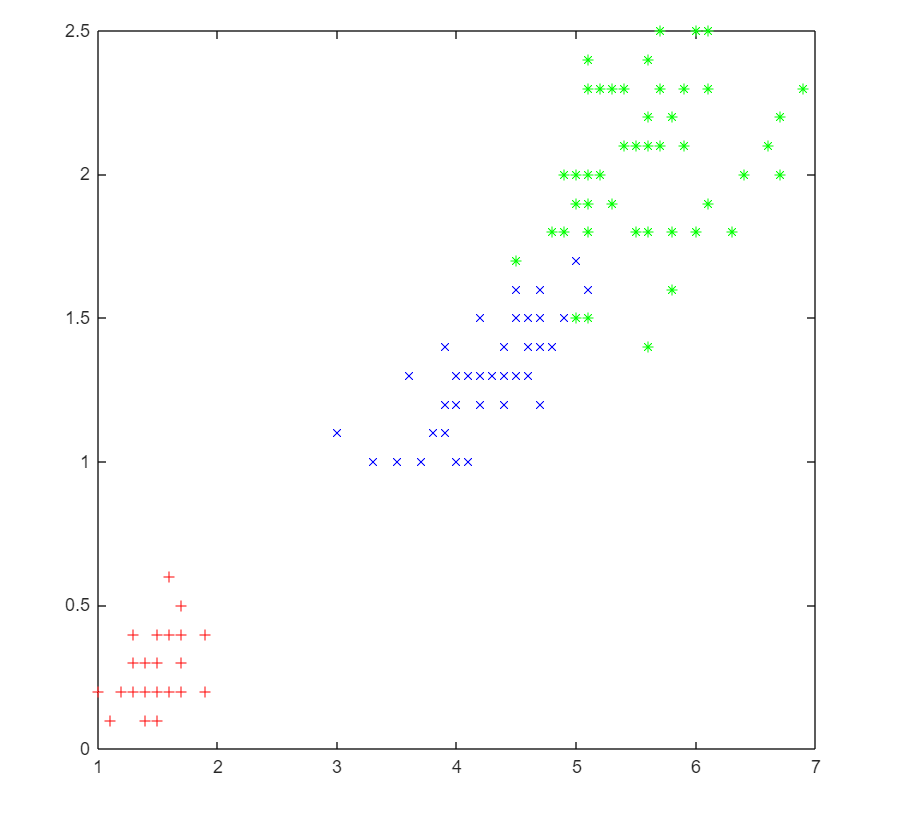

% Base de datos que se usara. Esta base de datos (que ya esta en contenida
% en la base de datos de Matlab) es la vista en la sesión de teoría, las de
% la variedades de la flor iris.

%%%%%%%%%%%%%%%%% Cargar datos ya que no funcionaba
load fisheriris
% La variable se llama 'meas' (medidas) y es de 150x4.
% Tu práctica espera 4x150, así que la transponemos con el apóstrofe (')
datos = meas';
%datos = iris_dataset;

% Trabajaremos con solo dos de las caracteristicas, es decir la longitud y
% amplitud del petalo.

datos_petalo = datos(3:4,1:150);

% Dividimos las caracteristicas en las tres clases según sus etiquetas y
% representamos gráficamente los resultados.

datos_petalo_setosa = datos_petalo(:,1:50);
datos_petalo_versicolor = datos_petalo(:,51:100);
datos_petalo_virginica = datos_petalo(:,101:150);

plot(datos_petalo_setosa(1,:),datos_petalo_setosa(2,:),'+',Color='r');
hold on
plot(datos_petalo_versicolor(1,:),datos_petalo_versicolor(2,:),'x',Color='b');
plot(datos_petalo_virginica(1,:),datos_petalo_virginica(2,:),'*',Color='g');
hold off

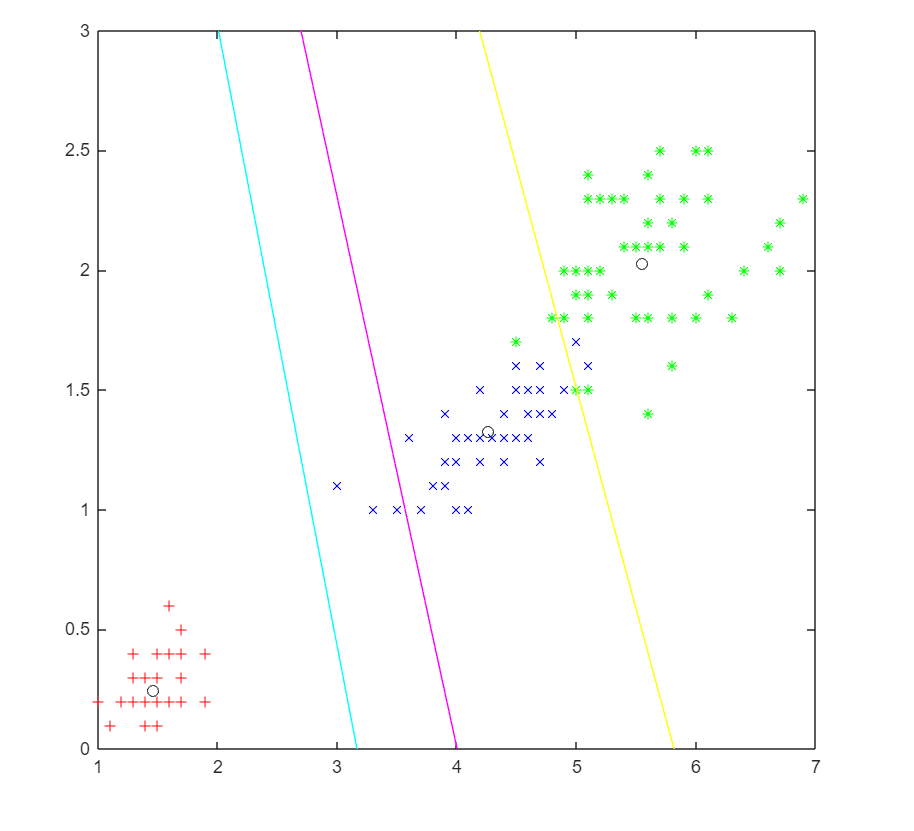

% Calculamos la caracteristica promedio de cada clase a traves de las
% formulas vista en la sesión de teoria. Estas características promedio son
% la media de las características etiquetadas en cada clase (esto es lo que
% las diferencia de los centroides de un k-means).

m1 = [mean(datos_petalo_setosa(1,:)),mean(datos_petalo_setosa(2,:))];
m2 = [mean(datos_petalo_versicolor(1,:)),mean(datos_petalo_versicolor(2,:))];
m3 = [mean(datos_petalo_virginica(1,:)),mean(datos_petalo_virginica(2,:))];

% Calculamos el hiperplano separador para cada par de clases de nuevo con
% las formulas vistas en clase.

x12 = linspace(0,8,100);
x13 = linspace(0,8,100);
x23 = linspace(0,8,100);

y12 = (0.5*dot((m1-m2),(m1+m2))-x12*(m1(1)-m2(1)))/(m1(2)-m2(2));
y13 = (0.5*dot((m1-m3),(m1+m3))-x13*(m1(1)-m3(1)))/(m1(2)-m3(2));
y23 = (0.5*dot((m2-m3),(m2+m3))-x23*(m2(1)-m3(1)))/(m2(2)-m3(2));

% Finalmente, representamos graficamente los resultados (cyan -> hiperplano
% entre clases 1 y 2, setosa y versicolor, magenta -> hiperplano entre cla- 
% ses 1 y 3, setosa y virginica, y amarillo -> hiperplano entre clases 2 y
% 3, versicolor y virginica.

plot(datos_petalo_setosa(1,:),datos_petalo_setosa(2,:),'+',Color='r');
hold on
plot(datos_petalo_versicolor(1,:),datos_petalo_versicolor(2,:),'x',Color='b');
plot(datos_petalo_virginica(1,:),datos_petalo_virginica(2,:),'*',Color='g');
plot(m1(1),m1(2),'o',Color='k');
plot(m2(1),m2(2),'o',Color='k');
plot(m3(1),m3(2),'o',Color='k');
plot(x12,y12,Color='c')
plot(x13,y13,Color='m')
plot(x23,y23,Color='y')
ylim([0 3])
hold off

## Adaboost y Viola-Jones

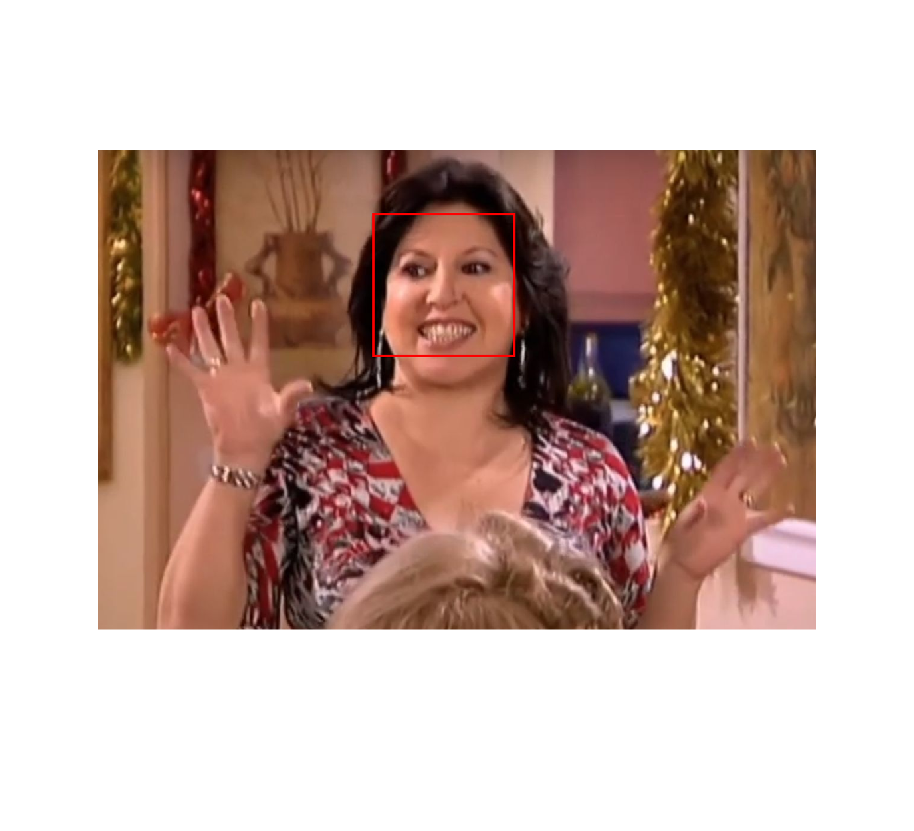

% Crea un objeto detector de caras basado en el algoritmo de Viola-Jones (con
% la función vision.CascadeObjectDetector(), que carga un modelo ya entrenado
% de dicho algoritmo) usando características de Haar relevantes en la detección
% de caras.

faceDetector = vision.CascadeObjectDetector();

% Función para detectar caras en la imagen. Inputs, el objeto detector
% creado y la imagen sobre la que hacer inferencia. Output, coordenadas
% de la bounding box o boxes de la cara o caras que puede haber en dicha
% imagen.

bbox_paloma = step(faceDetector, paloma);

% Dibuja los rectángulos o bounding boxes alrededor de las caras detectadas. 
% La función insertShape inserta una forma de las del tipo especificado con 
% las coordenadas indicadas y otros parámetros relacionados con la visualiza-
% ción

paloma_cara = insertShape(paloma, 'Rectangle', bbox_paloma,'LineWidth', 4,'Color','r');

montage({paloma_cara})

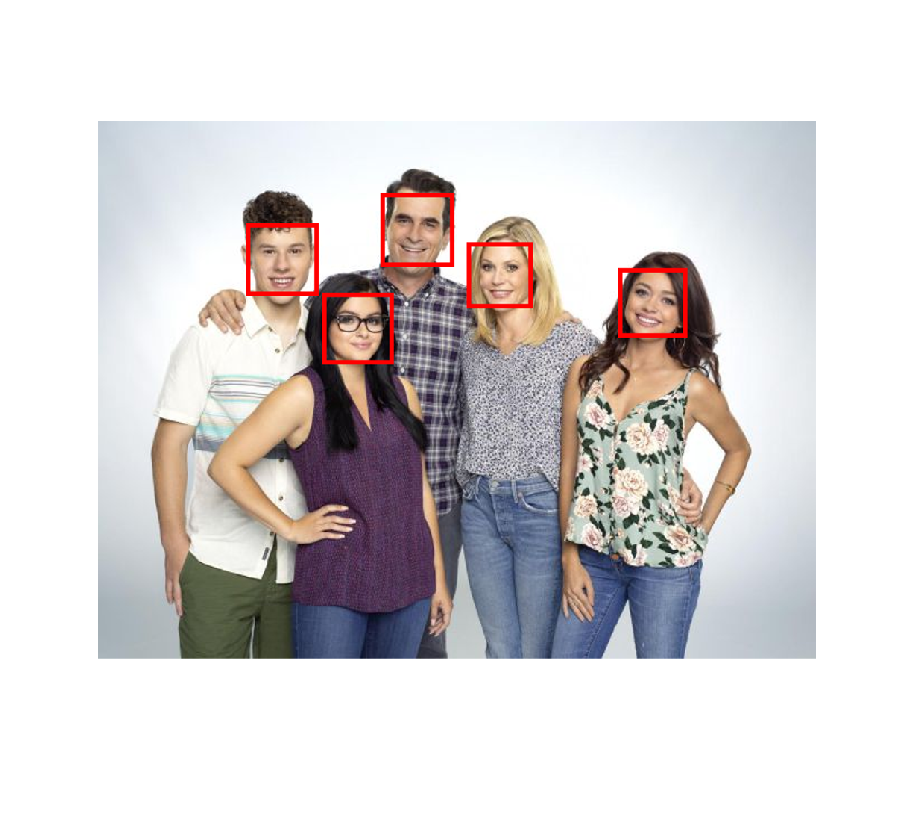


% Otro ejemplo (más de una cara)

bbox_familia = step(faceDetector, familia);

% Dibuja los rectángulos o bounding boxes alrededor de las caras detectadas

familia_cara = insertShape(familia, 'Rectangle', bbox_familia, 'LineWidth', 4, 'Color','r');

montage({familia_cara})

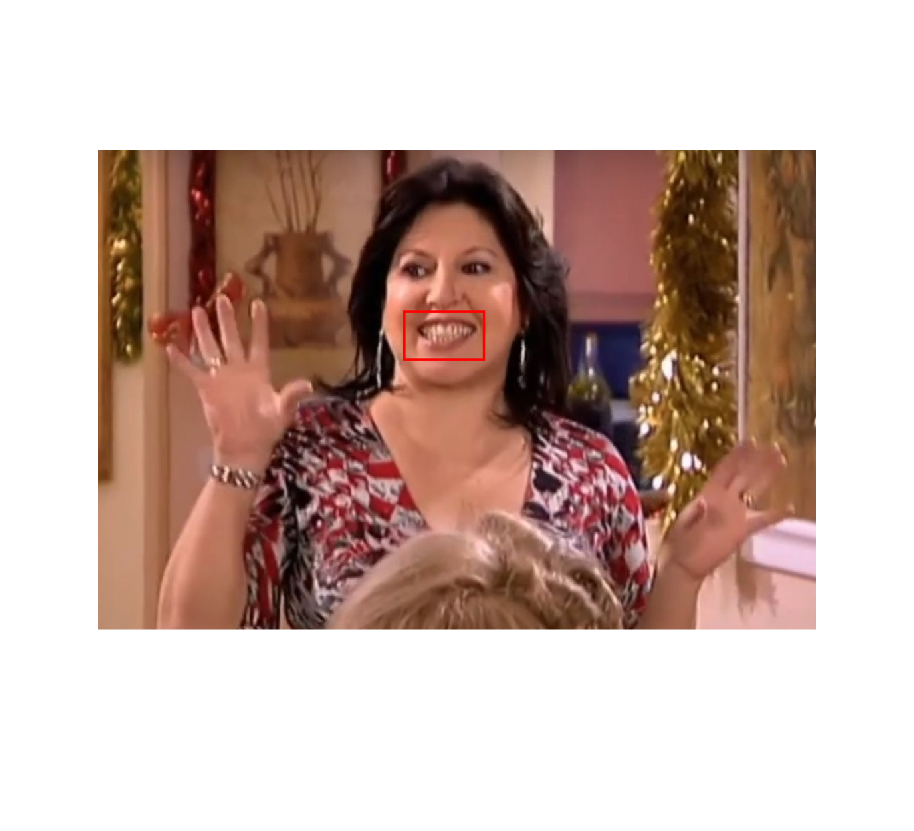

% El algoritmo Viola-Jones también se puede usar para detectar partes de 
% la cara. Posibilidades: Cara (vista frontal), parte superior del cuerpo,
% ojos, un ojo (izquierdo o derecho),caras (vista de perfil), boca y nariz.
% 
% Además, el paramétro "MergeThreshold" esta relacionado con el mecanismo
% de la cascada de atención porque sirve para eliminar las bounding boxes o
% rectangulos asociados a detecciones falsas (Viola-Jones tiene un ratio de
% falso positivos prácticamente cero para caras completas, pero dicho ratio
% aumenta para partes de cara). En este caso, es el número de síes necesa-
% rios en la cascada para dejar un elemento como verdadero, es decir, es
% una forma de filtrar detecciones poco robustas. Probad a cambiar el valor
% a uno más bajo o directamente quitarlo.

bocas_Detector = vision.CascadeObjectDetector('Mouth','MergeThreshold',20);

bbox_paloma_bocas = step(bocas_Detector, paloma);

% Dibuja los rectángulos o bounding boxes alrededor de las caras detectadas

paloma_bocas = insertShape(paloma, 'Rectangle', bbox_paloma_bocas, 'LineWidth', 4,Color='r');

montage({paloma_bocas})

# Ejercicios

## Reconocimiento y seguimiento de una cara en un video

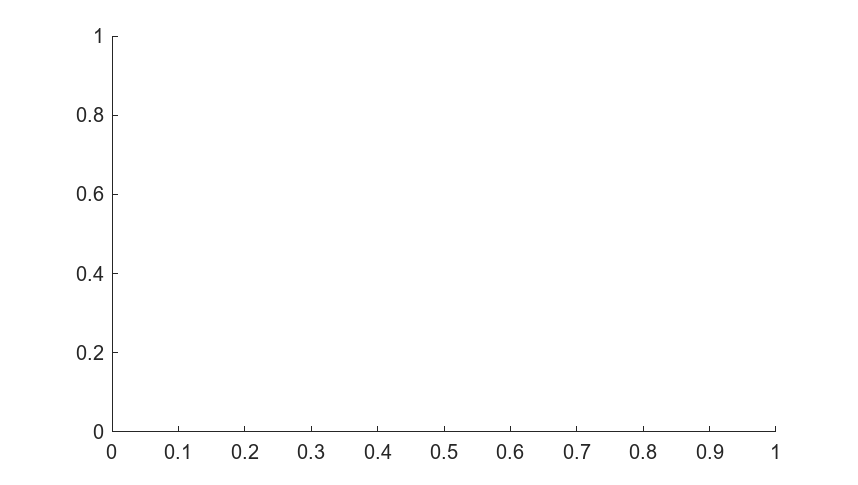

% EJ1 --> Para el video "obama", usar el algoritmo de Viola-Jones 
% para que la cara de Obama se muestre dentro de una bounding-box 
% DURANTE todo el video. Para manipular adecuadamente el video, 
% usar la función VideoReader de Matlab. Busca información concreta
% sobre usar esta función para extraer un frame concreto del video, 
% así como para hacer cambios en el video.

% Primero creamos el objeto detector de caras y cargamos el video
% Añadimos un threshold al detector ya que cuando no lo tenía detectaba
% algún que otro falso positivo en algun frame y de esta forma lo evitamos
faceDetector = vision.CascadeObjectDetector(MergeThreshold=20);
video = VideoReader('Obama.webm');

% Generaremos un bucle para procesar el video frame a frame
while hasFrame(video)
    frame = readFrame(video);
   
    % Detectamos la cara en el frame actual
    bbox = step(faceDetector, frame);
    
    % Insertamos la bounding box
    frame_marcado = insertShape(frame, 'Rectangle', bbox, 'LineWidth', 4, 'Color', 'yellow');

    % Mostramos el frame procesado
    imshow(frame_marcado);
    
    % Hemos visto que con 'drawnow' se fuerza a Matlab a actualizar la 
    % figura en cada iteración
    drawnow; 
end

## Uso del clasificador de la mínima distancia en 3D

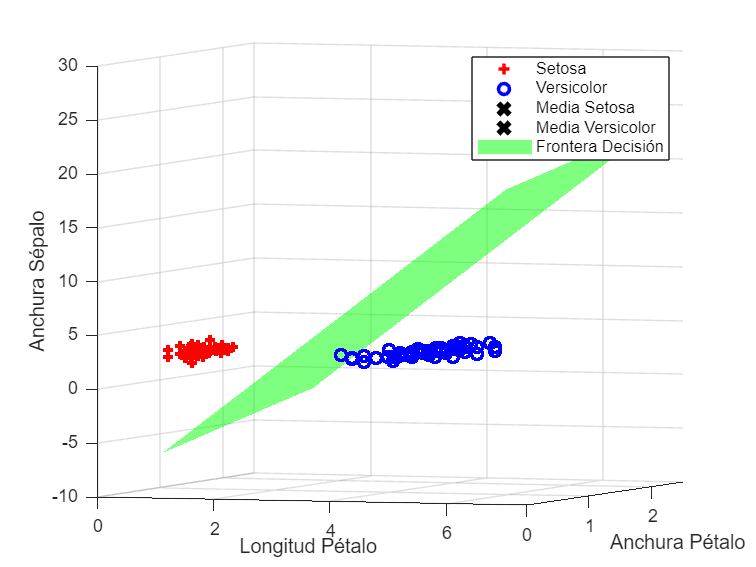

% EJ2 --> Para la base de datos "iris_dataset", y usando las formulas 
% de la sesión de teoría, mostrar el plano correspondiente a la frontera
% de decisión de las características "longitud pétalos","anchura pétalos"
% y "anchura sépalos" para las especies setosa y versicolor. Es decir,
% extender el caso visto en la sesión de prácticas de 2D a 3D.

% Cargamos los datos y seleccionamos características
% Filas: 3 (Long. pétalo), 4 (Anch. pétalo), 2 (Anch. sépalo)
load fisheriris
datos = meas';
feats = [3, 4, 2]; 

% Separamos las clases
clase_setosa = datos(feats, 1:50);
clase_versicolor = datos(feats, 51:100);

% Calculamos las medias de cada clase en 3D
% mean(..., 2) calcula la media a lo largo de las filas
m1 = mean(clase_setosa, 2);      % Media Setosa (vector 3x1)
m2 = mean(clase_versicolor, 2);  % Media Versicolor (vector 3x1)

% Definimos el plano de frontera de decisión
% La ecuación del plano equidistante es: (x - p0) * n = 0
% donde 'n' es el vector normal (m1 - m2) y 'p0' el punto medio (m1 + m2)/2.
% Si lo desarrollamos nos queda --> n(1)*x + n(2)*y + n(3)*z + D = 0

normal = m1 - m2;                % Vector normal al plano
punto_medio = (m1 + m2) / 2;     % Punto por el que pasa el plano
D = -dot(normal, punto_medio);   % Constante D

% Generamos la malla para dibujar el plano y cargamos los rangos
[x_grid, y_grid] = meshgrid(linspace(min(datos(3,:)), max(datos(3,:)), 20),linspace(min(datos(4,:)), max(datos(4,:)), 20));

% Despejamos z de la ecuación del plano: z = -(n1*x + n2*y + D) / n3
z_plane = -(normal(1)*x_grid + normal(2)*y_grid + D) / normal(3);

% Lo representamos
figure; hold on; grid on;
plot3(clase_setosa(1,:), clase_setosa(2,:), clase_setosa(3,:), 'r+', 'LineWidth', 2);
plot3(clase_versicolor(1,:), clase_versicolor(2,:), clase_versicolor(3,:), 'bo', 'LineWidth', 2);
plot3(m1(1), m1(2), m1(3), 'kx', 'MarkerSize', 10, 'LineWidth', 3);
plot3(m2(1), m2(2), m2(3), 'kx', 'MarkerSize', 10, 'LineWidth', 3);
surf(x_grid, y_grid, z_plane, 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'FaceColor', 'g');

xlabel('Longitud Pétalo'); ylabel('Anchura Pétalo'); zlabel('Anchura Sépalo');
legend('Setosa', 'Versicolor', 'Media Setosa', 'Media Versicolor', 'Frontera Decisión');
view(3); % Vista 3D
hold off;

## ICP con características

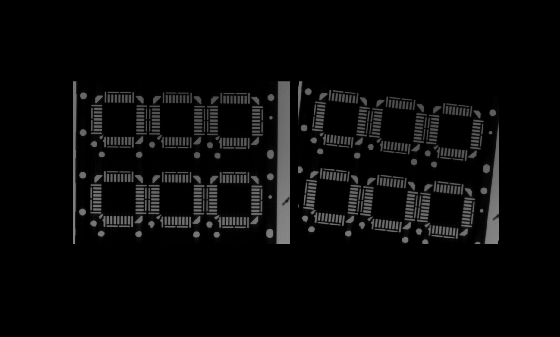

% EJ3 --> En la sesión de prácticas hemos visto que el algoritmo RANSAC 
% no siempre proporciona los mejores resultados al ajustar o alinear 
% objetos en imágenes distintas. 
%
% Para las imágenes "frame1" y "frame2", realiza los siguientes pasos:
%
% 1. Utiliza RANSAC para obtener un primer ajuste o alineación entre ambas imágenes.
% 2. A continuación, piensa cómo se puede emplear el algoritmo Iterative Closest Point (ICP)
%    para refinar la alineación de los objetos. En MATLAB, para aplicar ICP:
%
%    a) Obtén y empareja las características de ambas imágenes después del
%       ajuste inicial con RANSAC.
%    b) Extrae las coordenadas de las características emparejadas, es decir,
%       los puntos donde se localizan dichas características.
%    c) Convierte estos puntos al formato de nube de puntos de MATLAB usando
%       el comando "pointCloud()".
%    d) Aplica el algoritmo ICP con el comando "pcregistericp(pointCloud_1,pointCloud_2)"
%       Este algoritmo devuelve una transformación homogénea (similar a las vistas
%       en la asignatura de Introducció a la Robòtica en 1º), representada por:
%          - Una matriz de rotación: tform.R
%          - Un vector de traslación: tform.Translation
%          - O la matriz homogénea completa 4x4: tform.A
%    e) Aplica la transformación obtenida a la nube de puntos pointCloud_1 y 
%       visualiza el resultado para comprobar que ambas nubes están alineadas.
% Leer imágenes
I1 = imread('Frame 1.tif');
I2 = imread('Frame 2.tif');

% Convertir a escala de grises si es necesario
if size(I1,3) == 3; I1g = rgb2gray(I1); else; I1g = I1; end
if size(I2,3) == 3; I2g = rgb2gray(I2); else; I2g = I2; end
montage({I1,I2})

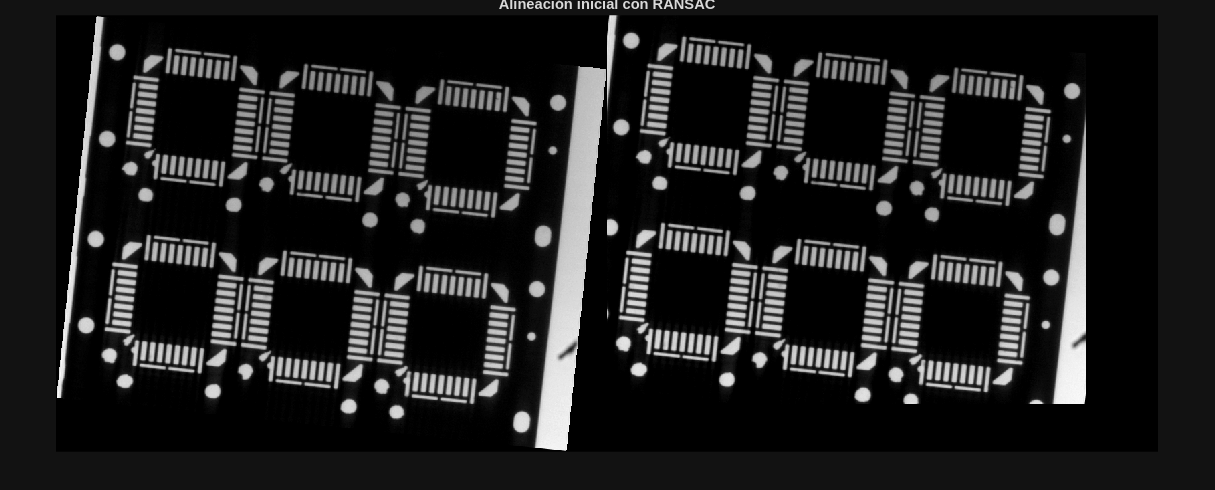


% Detectar puntos característicos
pts1 = detectSURFFeatures(I1g);
pts2 = detectSURFFeatures(I2g);

% Extraer descriptores
[features1, vpts1] = extractFeatures(I1g, pts1);
[features2, vpts2] = extractFeatures(I2g, pts2);

% Emparejar características
indexPairs = matchFeatures(features1, features2);
matched1 = vpts1(indexPairs(:,1));
matched2 = vpts2(indexPairs(:,2));

% RANSAC: estimar la transformación geométrica inicial
[tform_RANSAC, inlier1, inlier2] = estimateGeometricTransform2D( ...
    matched1, matched2, 'similarity', 'MaxNumTrials', 2000);

% Transformar la primera imagen para ver la alineación inicial
I1_RANSAC = imwarp(I1, tform_RANSAC);
figure; imshowpair(I1_RANSAC, I2, 'montage');
title('Alineación inicial con RANSAC');


% Transformar los puntos de I1 según RANSAC
[x1, y1] = transformPointsForward(tform_RANSAC, matched1.Location(:,1), matched1.Location(:,2));

% Emparejamientos después del ajuste inicial
pts1_transformed = [x1, y1];
pts2_original   = matched2.Location;
% Añadir coordenada Z = 0
pc1 = pointCloud([pts1_transformed, zeros(size(pts1_transformed,1), 1)]);
pc2 = pointCloud([pts2_original,    zeros(size(pts2_original,1), 1)]);



[tformICP, pcAligned, rmse] = pcregistericp(pc1, pc2);

disp('Rotación ICP:');

Rotación ICP:


disp(tformICP.R);

    1.0000    0.0003         0
   -0.0003    1.0000         0
         0         0    1.0000




disp('Traslación ICP:');

Traslación ICP:


disp(tformICP.Translation);

   -1.9973    0.8104         0




disp('Matriz homogénea 4x4:');

Matriz homogénea 4x4:


disp(tformICP.A);

    1.0000    0.0003         0   -1.9973
   -0.0003    1.0000         0    0.8104
         0         0    1.0000         0
         0         0         0    1.0000



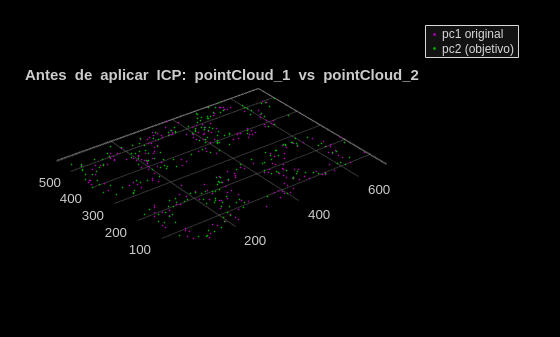


% visualitzacio abans de la transformacio
figure;
pcshowpair(pc1, pc2);
title('Antes de aplicar ICP: pointCloud\_1 vs pointCloud\_2');
legend({'pc1 original','pc2 (objetivo)'});

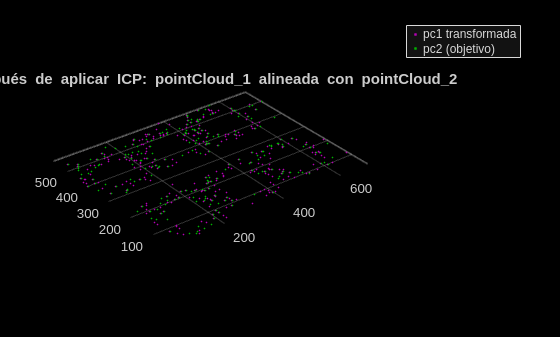


% apliquem la transformacio guardada a tformICP
pc1_ICP = pctransform(pc1, tformICP);

%visualitzacio despres de la transformacio
figure;
pcshowpair(pc1_ICP, pc2);
title('Después de aplicar ICP: pointCloud\_1 alineada con pointCloud\_2');
legend({'pc1 transformada','pc2 (objetivo)'});


% tot i que la diferencia es bastant poc notoria, podem veure com igual que
% amb la foto, la imatge queda lleugerament inclinanda en sentit
% antihorari, i si observem sobretot els punts al voltant de la coordenada
% (100,500), veiem que s'han alineat correctament en comparacio amb el
% nuvol de punts abans de la transformacio.

